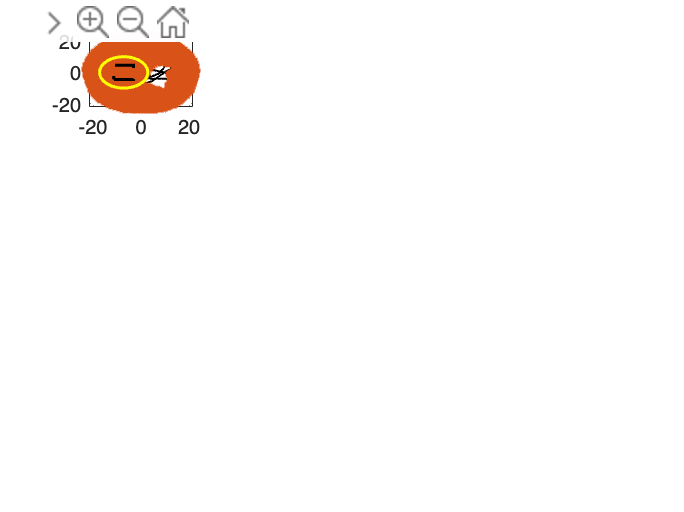

Error using  & 
Arrays have incompatible sizes for this operation.

Related documentation

%To analyze dummy
% IDs of flies (two flies per chamber)
individuals_IDs = 1:32;  % change accordingly

% Define the rectangular ROI (dummy)
roi_x_min = -11.39;  % Minimum x-coordinate
roi_x_max = -3.2;    % Maximum x-coordinate
roi_y_min = -4.6;    % Minimum y-coordinate
roi_y_max = 4.5;     % Maximum y-coordinate

% Define outer circular region
outer_radius = 10; % Radius from the center of dummy
x_center = (roi_x_min + roi_x_max) / 2;
y_center = (roi_y_min + roi_y_max) / 2;

% Number of chambers (pairs of flies)
num_bowls = length(individuals_IDs) / 2;

% Initialize variables to store time spent in dummy and outer circle
time_in_roi = zeros(2, num_bowls);  % Rows: fly 1 & fly 2, Columns: bowl
time_in_outer = zeros(2, num_bowls);  % Rows: fly 1 & fly 2, Columns: bowl

% Plot the trajectories for each pair with dummy colored
figure;
for i = 1:num_bowls
    % Get the IDs for the pair of flies in the bowl
    fly1_id = individuals_IDs(2*i - 1);
    fly2_id = individuals_IDs(2*i);
    
    % Create a subplot for the current chamber
    subplot(4, 4, i);  
    
    % Fly 1: Access its x_mm and y_mm positions
    posx1 = trxall(fly1_id).x_mm;  
    posy1 = trxall(fly1_id).y_mm;
    timestamps1 = trxall(fly1_id).timestamps;  
    
    % Fly 2: Access its x_mm and y_mm positions
    posx2 = trxall(fly2_id).x_mm;  
    posy2 = trxall(fly2_id).y_mm;
    timestamps2 = trxall(fly2_id).timestamps;  
    
    % Plot the trajectory for Fly 1
    plot(posx1, posy1, 'k-', 'LineWidth', 1);  % Blue for Fly 1
    hold on;
    
    % Plot the trajectory for Fly 2
    plot(posx2, posy2, 'p-', 'LineWidth', 1);  % Red for Fly 2
    
    % Plot the dummy as a rectangle
    rectangle('Position', [roi_x_min, roi_y_min, roi_x_max - roi_x_min, roi_y_max - roi_y_min], ...
              'EdgeColor', 'k', 'LineWidth', 1.5, 'LineStyle', '--');
    
    % Plot the outer circular region
    rectangle('Position', [x_center - outer_radius, y_center - outer_radius, 2*outer_radius, 2*outer_radius], ...
              'Curvature', [1, 1], 'EdgeColor', 'y', 'LineWidth', 1.5, 'LineStyle', '-');
    
    % Highlight trajectory points inside the dummy for Fly 1
    %in_roi1 = (posx1 >= roi_x_min & posx1 <= roi_x_max) & (posy1 >= roi_y_min & posy1 <= roi_y_max);
    %plot(posx1(in_roi1), posy1(in_roi1), 'bo', 'MarkerSize', 3, 'MarkerFaceColor', 'b');  % Blue points
    
    % Highlight trajectory points inside the dummy for Fly 2
    %in_roi2 = (posx2 >= roi_x_min & posx2 <= roi_x_max) & (posy2 >= roi_y_min & posy2 <= roi_y_max);
    %plot(posx2(in_roi2), posy2(in_roi2), 'ro', 'MarkerSize', 3, 'MarkerFaceColor', 'r');  % Red points
    
    % Calculate the time spent in the ROI for Fly 1
    if sum(in_roi1) > 1
        time_in_roi(1, i) = sum(diff(timestamps1(in_roi1)));  % Sum durations
    else
        time_in_roi(1, i) = 0;  % No time spent in ROI
    end
    
    % Calculate the time spent in dummy for Fly 2
    if sum(in_roi2) > 1
        time_in_roi(2, i) = sum(diff(timestamps2(in_roi2)));  % Sum durations
    else
        time_in_roi(2, i) = 0;  % No time spent in ROI
    end
    
    % Fly 1: In outer circular region but not in dummy
    in_outer1 = (sqrt((posx1 - x_center).^2 + (posy1 - y_center).^2) <= outer_radius) & ~in_roi1;
    plot(posx1(in_outer1), posy1(in_outer1), 'co', 'MarkerSize', 1, 'MarkerFaceColor', 'c'); % Cyan points for outer region
    if sum(in_outer1) > 1
        time_in_outer(1, i) = sum(diff(timestamps1(in_outer1)));  % Sum durations
    else
        time_in_outer(1, i) = 0;
    end

    % Fly 2: In outer circular region but not in dummy
    in_outer2 = (sqrt((posx2 - x_center).^2 + (posy2 - y_center).^2) <= outer_radius) & ~in_roi2;
    plot(posx2(in_outer2), posy2(in_outer2), 'mo', 'MarkerSize', 1, 'MarkerFaceColor', 'm'); % Magenta points for outer region
    if sum(in_outer2) > 1
        time_in_outer(2, i) = sum(diff(timestamps2(in_outer2)));  % Sum durations
    else
        time_in_outer(2, i) = 0;
    end
    
    % Title for each subplot
    title(['arena ', num2str(i)]);
    axis equal;  % Maintain aspect ratio
    xlim([-30, 30]);  % Adjust based on arena size
    ylim([-30, 30]);
    xticks([]);
    yticks([]);
    hold off;
end

sgtitle('Flies Trajectories');

% Plot histogram of time spent in ROI vs Outer region
figure;
time_comparison = cat(3, time_in_roi, time_in_outer);
bar(reshape(permute(time_comparison, [2, 3, 1]), [], 2), 'grouped');
xticks(1:2*num_chambers);
xticklabels(arrayfun(@(x) ['Fly ', num2str(x)], 1:2*num_chambers, 'UniformOutput', false));
xlabel('Fly');
ylabel('Time (seconds)');
legend({'dummy', 'Outer Region'}, 'Location', 'best');
title('Time Spent in dummy vs Outer Region');
grid on;

% Create a box plot for all flies' time spent in ROI and outer region
all_time_in_roi = time_in_roi(:);  % Flatten ROI times
all_time_in_outer = time_in_outer(:);  % Flatten outer region times

figure;
boxplot([all_time_in_roi, all_time_in_outer], ...
        'Labels', {'ROI', 'Outer Region'}, ...
        'Notch', 'on', 'Colors', [0.2, 0.6, 0.8; 0.8, 0.4, 0.2], ...
        'Widths', 0.5);
hold on;
median_roi = median(all_time_in_roi);
mean_roi = mean(all_time_in_roi);
median_outer = median(all_time_in_outer);
mean_outer = mean(all_time_in_outer);
yline(median_roi, '--b', 'Median ROI', 'LineWidth', 1.5);
yline(mean_roi, '-.b', 'Mean ROI', 'LineWidth', 1.5);
yline(median_outer, '--r', 'Median Outer', 'LineWidth', 1.5);
yline(mean_outer, '-.r', 'Mean Outer', 'LineWidth', 1.5);

xlabel('Region');
ylabel('Time (seconds)');
title('Time Spent in dummy vs Outer Region');
grid on;
hold off;
